clear variables

load('Tests/TlineNet/TlineNet_29par.mat')
training_samples = training_samples(1:960,:);
vouts_train = vouts_train(1:960,:);
[n_samples,d] = size(training_samples);
m = 2;


tic
vouts_total2 = pc_collocation_total(training_samples,vouts_train,samples,m ,'Hermite');
norm(vouts_total2-vouts,"fro")/norm(vouts,"fro")

ans = 0.0283

toc

Elapsed time is 0.938592 seconds.


load('Tests/TlineNet/TlineNet_29par.mat')
training_samples = training_samples2(1:9920,:);
vouts_train = vouts_train2(1:9920,:);
m = 3;

tic
vouts_total3 = pc_collocation_total(training_samples,vouts_train,samples,m ,'Hermite');
norm(vouts_total3-vouts,"fro")/norm(vouts,"fro")

ans = 0.0182

toc

Elapsed time is 27.453880 seconds.


load('Tests/TlineNet/TlineNet_29par.mat')
training_samples = training_samples(1:660,:);
vouts_train = vouts_train(1:660,:);
m = 3;

N = (m+1)*ones(d,1);
r = 3;
x = TTrand(N,r);
x{1}(1,:) = [1 zeros(1,r-1)];
for i = 1:d-1
    x{i}(1:r,:)=eye(r);
end
x{d}(1:r) = [vouts_train(1,1); zeros(r-1,1)];

tic
 [vouts_Newton,PC_coefficients_TT,training_err,test_err,n_iterations] = ...
     pc_collocation_tensor_optimization(training_samples,vouts_train,x,samples,m,'Hermite','TT-Newton',0.3,0.2,r);

ans =     0.0068    0.0078   10.0000


ans =     0.0066    0.0078    1.0000


ans =     0.0071    0.0088    1.0000


ans =     0.0079    0.0097    1.0000


ans =     0.0054    0.0071    2.0000


ans =     0.0059    0.0078    1.0000


ans =     0.0069    0.0089    1.0000


ans =     0.0046    0.0064    2.0000


ans =     0.0055    0.0074    1.0000


ans =     0.0072    0.0089    1.0000


ans =     0.0043    0.0055    2.0000


ans =     0.0053    0.0066    1.0000


ans =     0.0069    0.0081    1.0000


ans =     0.0083    0.0098    1.0000


ans =     0.0046    0.0056    2.0000


ans =     0.0057    0.0074    1.0000


ans =     0.0072    0.0088    1.0000


ans =     0.0043    0.0058    2.0000


ans =     0.0053    0.0075    1.0000


ans =     0.0068    0.0085    1.0000


ans =     0.0041    0.0055    2.0000


ans =     0.0051    0.0068    1.0000


ans =     0.0072    0.0094    1.0000


ans =     0.0044    0.0059    2.0000


ans =     0.0059    0.0083    1.0000


ans =     0.0042    0.0063    2.0000


ans =     0.0056    0.0081    1.0000


ans =     0.0042    0.0061    2.0000


ans =     0.0059    0.0079    1.0000


ans =     0.0039    0.0052    2.0000


ans =     0.0052    0.0069    1.0000


ans =     0.0072    0.0095    1.0000


ans =     0.0043    0.0056    2.0000


ans =     0.0055    0.0074    1.0000


ans =     0.0073    0.0094    1.0000


ans =     0.0042    0.0056    2.0000


ans =     0.0052    0.0069    1.0000


ans =     0.0067    0.0088    1.0000


ans =     0.0041    0.0054    2.0000


ans =     0.0048    0.0067    1.0000


ans =     0.0060    0.0078    1.0000


ans =     0.0074    0.0094    1.0000


ans =     0.0045    0.0066    2.0000


ans =     0.0049    0.0072    1.0000


ans =     0.0061    0.0085    1.0000


ans =     0.0073    0.0098    1.0000


ans =     0.0042    0.0063    2.0000


ans =     0.0046    0.0070    1.0000


ans =     0.0058    0.0081    1.0000


ans =     0.0071    0.0093    1.0000


ans = 1×3
    0.0043    0.0059    2.0000


ans = 1×3
    0.0047    0.0066    1.0000


ans = 1×3
    0.0057    0.0078    1.0000


ans = 1×3
    0.0069    0.0094    1.0000


ans = 1×3
    0.0042    0.0053    2.0000


ans = 1×3
    0.0045    0.0060    1.0000


ans = 1×3
    0.0054    0.0073    1.0000


ans = 1×3
    0.0066    0.0090    1.0000


ans = 1×3
    0.0042    0.0058    2.0000


ans = 1×3
    0.0048    0.0071    1.0000


ans = 1×3
    0.0060    0.0087    1.0000


ans = 1×3
    0.0041    0.0061    2.0000


ans = 1×3
    0.0048    0.0074    1.0000


ans = 1×3
    0.0065    0.0093    1.0000


ans = 1×3
    0.0048    0.0074    2.0000


ans = 1×3
    0.0061    0.0091    1.0000


ans = 1×3
    0.0055    0.0085    2.0000


ans = 1×3
    0.0041    0.0136   10.0000


ans = 1×3
    0.0064    0.0222    8.0000


ans = 1×3
    0.0102    0.0356    8.0000


ans = 1×3
    0.0156    0.0535   10.0000


ans = 1×3
    0.0226    0.0741   10.0000


ans = 1×3
    0.0297    0.0969   10.0000


ans = 1×3
    0.0354    0.1256   12.0000


ans = 1×3
    0.0378    0.1524   11.0000


ans = 1×3
    0.0404    0.1692    2.0000


ans = 1×3
    0.0402    0.1813    2.0000


ans = 1×3
    0.0389    0.1766    1.0000


ans = 1×3
    0.0299    0.1627    2.0000


ans = 1×3
    0.0255    0.1252    1.0000


ans = 1×3
    0.0177    0.0894    2.0000


ans = 1×3
    0.0111    0.0557    2.0000


ans = 1×3
    0.0075    0.0343    2.0000


ans = 1×3
    0.0045    0.0191    4.0000


ans = 1×3
    0.0026    0.0106    5.0000


ans = 1×3
    0.0074    0.0083    1.0000


ans = 1×3
    0.0065    0.0133   13.0000


ans = 1×3
    0.0120    0.0234   15.0000


ans = 1×3
    0.0106    0.0278   14.0000


ans = 1×3
    0.0055    0.0221    8.0000


ans = 1×3
    0.0039    0.0160    3.0000


ans = 1×3
    0.0025    0.0110    4.0000


ans = 1×3
    0.0044    0.0082    1.0000


ans = 1×3
    0.0071    0.0094    1.0000


ans = 1×3
    0.0048    0.0068    2.0000


ans = 1×3
    0.0064    0.0083    1.0000


ans = 1×3
    0.0044    0.0067    2.0000


ans = 1×3
    0.0057    0.0087    1.0000


ans = 1×3
    0.0045    0.0077    2.0000


ans = 1×3
    0.0037    0.0073    2.0000


norm(vouts_Newton-vouts,"fro")/norm(vouts,"fro")

ans = 0.0147

toc

Elapsed time is 17.523083 seconds.


load('Tests/TlineNet/TlineNet_29par.mat')
training_samples = training_samples(1:660,:);
vouts_train = vouts_train(1:660,:);
m = 3;

N = (m+1)*ones(d,1);
r = 3;
x = TTrand(N,r);
x{1}(1,:) = [1 zeros(1,r-1)];
for i = 1:d-1
    x{i}(1:r,:)=eye(r);
end
x{d}(1:r) = [vouts_train(1,1); zeros(r-1,1)];

tic
 [vouts_ALS,PC_coefficients_ALS,training_err,test_err,n_iterations] = ...
     pc_collocation_tensor_optimization(training_samples,vouts_train,x,samples,m,'Hermite','TT-ALS',0.3,0.2,r);

ans =     0.0043    0.0099  186.0000


ans =     0.0052    0.0100    9.0000


ans =     0.0050    0.0099   23.0000


ans =     0.0052    0.0093   24.0000


ans =     0.0046    0.0100   23.0000


ans =     0.0047    0.0098   25.0000


ans =     0.0044    0.0098   24.0000


ans =     0.0042    0.0097   25.0000


ans =     0.0043    0.0100   24.0000


ans =     0.0043    0.0099   26.0000


ans =     0.0041    0.0098   27.0000


ans =     0.0037    0.0090   28.0000


ans =     0.0040    0.0099   15.0000


ans =     0.0038    0.0096   28.0000


ans =     0.0039    0.0096   23.0000


ans =     0.0041    0.0097   26.0000


ans =     0.0041    0.0099   26.0000


ans =     0.0042    0.0094   28.0000


ans =     0.0041    0.0099   24.0000


ans =     0.0041    0.0098   28.0000


ans =     0.0042    0.0097   26.0000


ans =     0.0045    0.0099   26.0000


ans =     0.0044    0.0098   28.0000


ans =     0.0046    0.0099   26.0000


ans =     0.0040    0.0099   29.0000


ans =     0.0039    0.0100   32.0000


ans =     0.0040    0.0100   35.0000


ans =     0.0040    0.0100   35.0000


ans =     0.0042    0.0100   28.0000


ans =     0.0041    0.0099   28.0000


ans =     0.0044    0.0099   26.0000


ans =     0.0042    0.0098   27.0000


ans =     0.0045    0.0099   26.0000


ans =     0.0045    0.0099   27.0000


ans =     0.0045    0.0093   28.0000


ans =     0.0048    0.0100   16.0000


ans =     0.0041    0.0100   39.0000


ans =     0.0048    0.0100   20.0000


ans =     0.0039    0.0097   42.0000


ans =     0.0046    0.0098   24.0000


ans =     0.0044    0.0099   26.0000


ans =     0.0046    0.0100   24.0000


ans =     0.0041    0.0098   28.0000


ans =     0.0046    0.0099   19.0000


ans =     0.0040    0.0100   35.0000


ans =     0.0045    0.0096   24.0000


ans =     0.0043    0.0099   26.0000


ans =     0.0040    0.0098   26.0000


ans =     0.0045    0.0100   24.0000


ans =     0.0041    0.0097   28.0000


ans = 1×3
    0.0045    0.0100   20.0000


ans = 1×3
    0.0042    0.0098   28.0000


ans = 1×3
    0.0045    0.0098   23.0000


ans = 1×3
    0.0042    0.0099   27.0000


ans = 1×3
    0.0045    0.0098   24.0000


ans = 1×3
    0.0044    0.0097   26.0000


ans = 1×3
    0.0046    0.0100   24.0000


ans = 1×3
    0.0045    0.0100   28.0000


ans = 1×3
    0.0043    0.0100   28.0000


ans = 1×3
    0.0046    0.0106   36.0000


ans = 1×3
    0.0052    0.0119   35.0000


ans = 1×3
    0.0061    0.0138   35.0000


ans = 1×3
    0.0072    0.0163   35.0000


ans = 1×3
    0.0087    0.0194   35.0000


ans = 1×3
    0.0106    0.0234   35.0000


ans = 1×3
    0.0132    0.0287   35.0000


ans = 1×3
    0.0168    0.0358   35.0000


ans = 1×3
    0.0216    0.0454   35.0000


ans = 1×3
    0.0118    0.0291  173.0000


ans = 1×3
    0.0176    0.0470   91.0000


ans = 1×3
    0.0231    0.0663   91.0000


ans = 1×3
    0.0292    0.0864   90.0000


ans = 1×3
    0.0350    0.1043   91.0000


ans = 1×3
    0.0370    0.1207  207.0000


ans = 1×3
    0.0385    0.1345  146.0000


ans = 1×3
    0.0362    0.1452  104.0000


ans = 1×3
    0.0359    0.1455   47.0000


ans = 1×3
    0.0329    0.1316   36.0000


ans = 1×3
    0.0295    0.1194   24.0000


ans = 1×3
    0.0242    0.0971   48.0000


ans = 1×3
    0.0161    0.0660   69.0000


ans = 1×3
    0.0120    0.0394   91.0000


ans = 1×3
    0.0155    0.0312   35.0000


ans = 1×3
    0.0101    0.0231   91.0000


ans = 1×3
    0.0090    0.0208   91.0000


ans = 1×3
    0.0087    0.0212   91.0000


ans = 1×3
    0.0108    0.0255   91.0000


ans = 1×3
    0.0139    0.0327  147.0000


ans = 1×3
    0.0145    0.0344   91.0000


ans = 1×3
    0.0082    0.0237   91.0000


ans = 1×3
    0.0052    0.0154   91.0000


ans = 1×3
    0.0068    0.0118   36.0000


ans = 1×3
    0.0056    0.0099   27.0000


ans = 1×3
    0.0055    0.0099   15.0000


ans = 1×3
    0.0059    0.0098   17.0000


ans = 1×3
    0.0053    0.0095   26.0000


ans = 1×3
    0.0048    0.0100   26.0000


ans = 1×3
    0.0044    0.0099   28.0000


ans = 1×3
    0.0043    0.0100   27.0000


ans = 1×3
    0.0040    0.0101   36.0000


norm(vouts_ALS-vouts,"fro")/norm(vouts,"fro")

ans = 0.0174

toc

Elapsed time is 23.736591 seconds.


load('Tests/TlineNet/TlineNet_29par.mat')
training_samples = training_samples(1:660,:);
vouts_train = vouts_train(1:660,:);
m = 3;
r = 8;
x = cell(d,1);
for i = 1:d
    x{i} = zeros(m+1,1);
end


tic
 [vouts_GD,PC_coefficients_GD,training_err,test_err,n_iterations] = ...
     pc_collocation_tensor_optimization(training_samples,vouts_train,x,samples,m,'Hermite','TT-SGD',0.3,0.2,r,60,10);

ans =     0.0009    0.0098   27.0000


ans =     0.0009    0.0098   28.0000


ans =     0.0011    0.0099   29.0000


ans =     0.0008    0.0097   35.0000


ans =     0.0008    0.0098   24.0000


ans =     0.0008    0.0093   38.0000


ans =     0.0013    0.0098   26.0000


ans =     0.0010    0.0098   40.0000


ans =     0.0009    0.0097   28.0000


ans =     0.0008    0.0097   38.0000


ans =     0.0007    0.0097   34.0000


ans =     0.0008    0.0097   32.0000


ans =     0.0007    0.0097   44.0000


ans =     0.0007    0.0099   39.0000


ans =     0.0007    0.0095   50.0000


ans =     0.0009    0.0098   43.0000


ans =     0.0008    0.0095   34.0000


ans =     0.0007    0.0095   38.0000


ans =     0.0009    0.0100   36.0000


ans =     0.0006    0.0094   47.0000


ans =     0.0006    0.0096   55.0000


ans =     0.0005    0.0096   57.0000


ans =     0.0007    0.0100   46.0000


ans =     0.0009    0.0096   36.0000


ans =     0.0007    0.0097   37.0000


ans =     0.0007    0.0098   60.0000


ans =     0.0005    0.0100   60.0000


ans =     0.0006    0.0100   56.0000


ans =     0.0009    0.0098   49.0000


ans =     0.0007    0.0098   58.0000


ans =     0.0007    0.0094   50.0000


ans =     0.0008    0.0098   48.0000


ans =     0.0008    0.0098   54.0000


ans =     0.0009    0.0098   47.0000


ans =     0.0007    0.0099   55.0000


ans =     0.0008    0.0097   57.0000


ans =     0.0008    0.0096   50.0000


ans =     0.0008    0.0097   47.0000


ans =     0.0007    0.0099   47.0000


ans =     0.0007    0.0099   56.0000


ans =     0.0007    0.0098   57.0000


ans =     0.0006    0.0097   60.0000


ans =     0.0007    0.0100   64.0000


ans =     0.0007    0.0099   59.0000


ans =     0.0008    0.0097   57.0000


ans =     0.0007    0.0097   56.0000


ans =     0.0007    0.0097   53.0000


ans =     0.0008    0.0100   49.0000


ans =     0.0008    0.0098   59.0000


ans =     0.0007    0.0098   64.0000


ans = 1×3
    0.0009    0.0099   59.0000


ans = 1×3
    0.0007    0.0098   68.0000


ans = 1×3
    0.0007    0.0098   58.0000


ans = 1×3
    0.0008    0.0097   56.0000


ans = 1×3
    0.0006    0.0099   69.0000


ans = 1×3
    0.0006    0.0098   67.0000


ans = 1×3
    0.0006    0.0099   73.0000


ans = 1×3
    0.0006    0.0098   69.0000


ans = 1×3
    0.0006    0.0100   98.0000


ans = 1×3
    0.0007    0.0100  100.0000


ans = 1×3
    0.0007    0.0126  100.0000


ans = 1×3
    0.0009    0.0130  100.0000


ans = 1×3
    0.0009    0.0158  100.0000


ans = 1×3
    0.0014    0.0172  100.0000


ans = 1×3
    0.0012    0.0203  100.0000


ans = 1×3
    0.0017    0.0240  100.0000


ans = 1×3
    0.0031    0.0325  100.0000


ans = 1×3
    0.0028    0.0424  100.0000


ans = 1×3
    0.0028    0.0575  100.0000


ans = 1×3
    0.0046    0.0767  100.0000


ans = 1×3
    0.0063    0.1033  100.0000


ans = 1×3
    0.0078    0.1418  100.0000


ans = 1×3
    0.0085    0.1657  100.0000


ans = 1×3
    0.0110    0.1743  100.0000


ans = 1×3
    0.0148    0.1937   78.0000


ans = 1×3
    0.0115    0.1949  100.0000


ans = 1×3
    0.0088    0.2033  100.0000


ans = 1×3
    0.0079    0.2123  100.0000


ans = 1×3
    0.0066    0.2060  100.0000


ans = 1×3
    0.0043    0.1856  100.0000


ans = 1×3
    0.0039    0.1547  100.0000


ans = 1×3
    0.0037    0.1144  100.0000


ans = 1×3
    0.0030    0.0793  100.0000


ans = 1×3
    0.0016    0.0556  100.0000


ans = 1×3
    0.0017    0.0413  100.0000


ans = 1×3
    0.0017    0.0321  100.0000


ans = 1×3
    0.0028    0.0411   85.0000


ans = 1×3
    0.0047    0.0587  100.0000


ans = 1×3
    0.0056    0.0740  100.0000


ans = 1×3
    0.0027    0.0676  100.0000


ans = 1×3
    0.0025    0.0529  100.0000


ans = 1×3
    0.0016    0.0446  100.0000


ans = 1×3
    0.0013    0.0360  100.0000


ans = 1×3
    0.0012    0.0318  100.0000


ans = 1×3
    0.0009    0.0252  100.0000


ans = 1×3
    0.0011    0.0250  100.0000


ans = 1×3
    0.0010    0.0226  100.0000


ans = 1×3
    0.0010    0.0210  100.0000


ans = 1×3
    0.0011    0.0211  100.0000


ans = 1×3
    0.0012    0.0188  100.0000


norm(vouts_GD-vouts,"fro")/norm(vouts,"fro")

ans = 0.0260

toc

Elapsed time is 105.998578 seconds.



scale = 1e9;

fpoints = linspace(0,3e9,100);
f = figure(2);
subplot(2,1,1);
hold on
plot(fpoints/scale,vout_mean0,'k-','LineWidth',3);
plot(fpoints/scale,vout_mean1,'g--','LineWidth',2);
legend('Monte Carlo simulation','TT-Newton')
grid on
xlabel('Frequency (GHz)','interpreter','LaTex')
ylabel('Mean of $ \mid V_{out} \mid $ (V)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;


subplot(2,1,2);
hold on
plot(fpoints/scale,vout_sigma0,'k-','LineWidth',3);
plot(fpoints/scale,vout_sigma1,'g--','LineWidth',2);
ylim([0.0 0.03])
grid on
ylabel('Standard devation of $ V_{out} $ (V)','interpreter','LaTex')
xlabel('Frequency (GHz)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;

f.Position = [100 100 675 500];

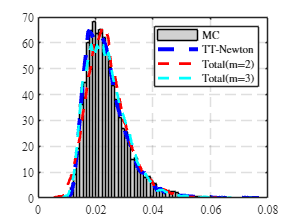

pdf_freq_idx = 70;
figure(1)
histogram(abs(vouts(:,pdf_freq_idx)),50,'Normalization','pdf', 'DisplayStyle','bar', 'FaceColor',[0.7 0.7 0.7]);
hold on
grid on
[N,edges] = histcounts(abs(vouts_Newton(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'b--','LineWidth',3)
[N,edges] = histcounts(abs(vouts_total2(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'r--','LineWidth',2)
[N,edges] = histcounts(abs(vouts_total3(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'c--','LineWidth',2)
[N,edges] = histcounts(abs(vouts_GD(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'--','LineWidth',2)
[N,edges] = histcounts(abs(vouts_ALS(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'--','LineWidth',2)
xlim([0.02 0.08])
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
legend('MC', 'TT-Newton','Total(m=2)','Total(m=3)','interpreter','LaTex')